% Erstellen der point cloud
x = 1:3;
y= 1:0.1:5;
[x,y] = meshgrid(x,y)

x =      1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3


y =     1.0000    1.0000    1.0000
    1.1000    1.1000    1.1000
    1.2000    1.2000    1.2000
    1.3000    1.3000    1.3000
    1.4000    1.4000    1.4000
    1.5000    1.5000    1.5000
    1.6000    1.6000    1.6000
    1.7000    1.7000    1.7000
    1.8000    1.8000    1.8000
    1.9000    1.9000    1.9000



% Seed setzen für die random Zahlen, damit diese vergleichbar bleiben
rng(42);

A = x.^2 + y.^2

A =     2.0000    5.0000   10.0000
    2.2100    5.2100   10.2100
    2.4400    5.4400   10.4400
    2.6900    5.6900   10.6900
    2.9600    5.9600   10.9600
    3.2500    6.2500   11.2500
    3.5600    6.5600   11.5600
    3.8900    6.8900   11.8900
    4.2400    7.2400   12.2400
    4.6100    7.6100   12.6100


ptCloud = pointCloud(A);

% Generate Gaussian noise
gaussNoise = 0.5 * randn(size(ptCloud.Location));
ptCloud = pointCloud(ptCloud.Location + gaussNoise, 'Color', ptCloud.Color);
disp(ptCloud.Location(1:10, :));

    1.7309    4.5600    9.6773
    2.6436    5.7643   10.6009
    2.9280    5.2079   10.5978
    2.8587    6.0223   11.3272
    2.4620    5.6949   10.9227
    2.9884    6.2705   10.0982
    2.9113    6.6375   12.0528
    4.3487    6.7295   12.4018
    4.3283    8.3129   12.3058
    4.9876    8.0102   12.9110



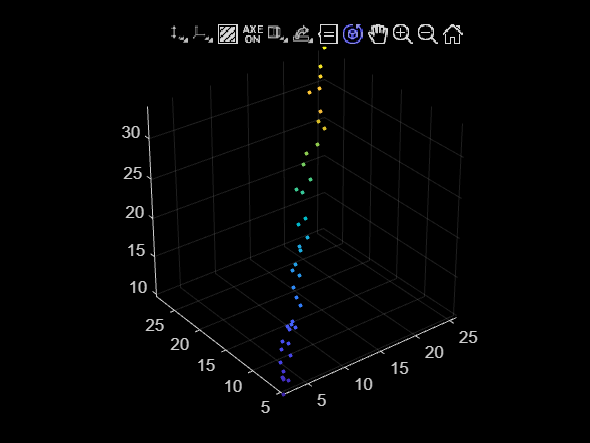

pcshow(ptCloud, 'MarkerSize', 50);

%title('fix');

% Erzeuge leicht gestörte Punktwolke für die Schätzung
tformNoisy = rigidtform3d([0.1 0.2 2], [2 2 5]);
gaussNoise = 0.8 * randn(size(ptCloud.Location));
ptCloudTformedNoisy = pointCloud(ptCloud.Location + gaussNoise, 'Color', ptCloud.Color);
disp(ptCloudTformedNoisy.Location(1:10, :));

    2.4259    2.8421    9.0238
    1.9118    5.9445   10.7191
    2.9555    5.5042   11.0424
    2.6585    4.5178   12.2157
    1.6159    5.7373   10.5020
    2.2993    5.7103   10.2368
    2.6284    6.8115   11.4102
    5.0123    5.3057   12.1354
    4.0333    8.7287   12.8213
    5.0369    7.7258   13.3938



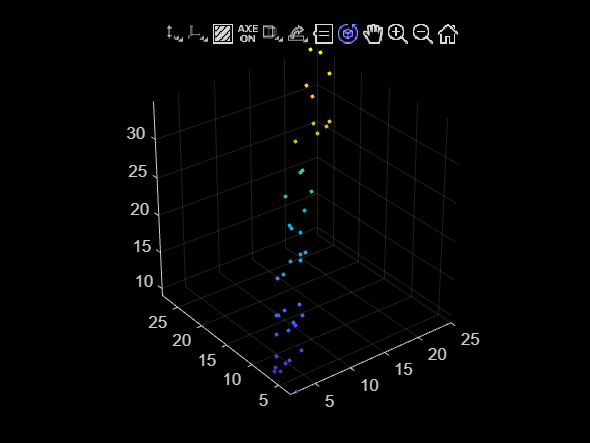


pcshow(ptCloudTformedNoisy, 'MarkerSize', 50)

%title('moved');
%pcshowpair(ptCloud,ptCloudTformedNoisy, 'MarkerSize', 50)
%title('fix und moved');

%register the two point clouds -> hier wird die notwendige matrix
%gespeichert, um die Wolken aneinander anzupassen
[tformEstimated,temp,rmse]= pcregistericp(ptCloudTformedNoisy,ptCloud);
disp(rmse);

    1.3736



disp(tformEstimated);

  rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-0.4908 0.8586 -0.1856]
                 R: [3×3 double]
                 A: [4×4 double]




% Transformiere die Punktwolke mit der geschätzten Transformation
ptCloudTformedEstimated = pctransform(ptCloudTformedNoisy, tformEstimated);
%pcshow(ptCloudTformedEstimated, 'MarkerSize', 50);
%title('geschätzte transformation');

% Vergleiche die Transformationen
disp('True Transformation:');

True Transformation:


disp(tformNoisy.A);

    0.9994   -0.0349    0.0035    2.0000
    0.0349    0.9994   -0.0016    2.0000
   -0.0035    0.0017    1.0000    5.0000
         0         0         0    1.0000




disp('invertiert:');

invertiert:


tformInvert = invert(tformNoisy);
disp(tformInvert.A);

    0.9994    0.0349   -0.0035   -2.0511
   -0.0349    0.9994    0.0017   -1.9377
    0.0035   -0.0016    1.0000   -5.0038
         0         0         0    1.0000




disp('Abziehen Transf und Invertierter:');

Abziehen Transf und Invertierter:


disp(tformNoisy.A - tformEstimated.A);

    0.0122    0.0721   -0.1145    2.4908
   -0.0838    0.0111    0.0948    1.1414
    0.1029   -0.1074    0.0117    5.1856
         0         0         0         0




disp('Estimated Transformation:');

Estimated Transformation:


disp(tformEstimated.A);

    0.9872   -0.1070    0.1181   -0.4908
    0.1187    0.9882   -0.0964    0.8586
   -0.1064    0.1092    0.9883   -0.1856
         0         0         0    1.0000





% Berechnung des RMSE
rmse = sqrt(sum(((ptCloud.Location-ptCloudTformedEstimated.Location).^2)/2));
% Anzeige des RMSE-Werts
disp(['RMSE: ', num2str(rmse)]);

RMSE: 3.037       4.744      4.3096
